# Exergy Cost Calculator Demo

Use ExergyCostCalculator function to compute direct and generalized exergy cost

#### Select the model file

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(1));
Samples=convertCharsToStrings(data.ResourceSamples);
ResourceSample=convertStringsToChars(Samples(2));

#### Compute Exergy Cost

res=ExergyCostCalculator(data,'State',State,...
    'CostTables','ALL',...
    'ResourceSample',ResourceSample);
printResults(res);

Flows Exergy Cost

 Key         B(kW)      B*(kW)     Be*(kW)     Br*(kW)     k*(J/J)    ke*(J/J)    kr*(J/J)
-------------------------------------------------------------------------------------------
 B1         82.730     131.081     114.111      16.970      1.5844      1.3793      0.2051
 B2         17.270      27.363      23.821       3.542      1.5844      1.3793      0.2051
 B3         15.210      24.099      20.979       3.120      1.5844      1.3793      0.2051
 B4          5.693       9.020       7.852       1.168      1.5844      1.3793      0.2051
 B5          7.766      14.039      12.039       2.000      1.8078      1.5503      0.2575
 B6          9.266      17.613      14.881       2.732      1.9008      1.6059      0.2948
 QBLR       99.230      99.230      99.230       0.000      1.0000      1.0000      0.0000
 WP          2.424       4.825       4.187       0.638      1.9906      1.7272      0.2633
 WN         49.850      99.230      86.103      13.127      1.9906    

#### Show Irreversibility Cost Graph

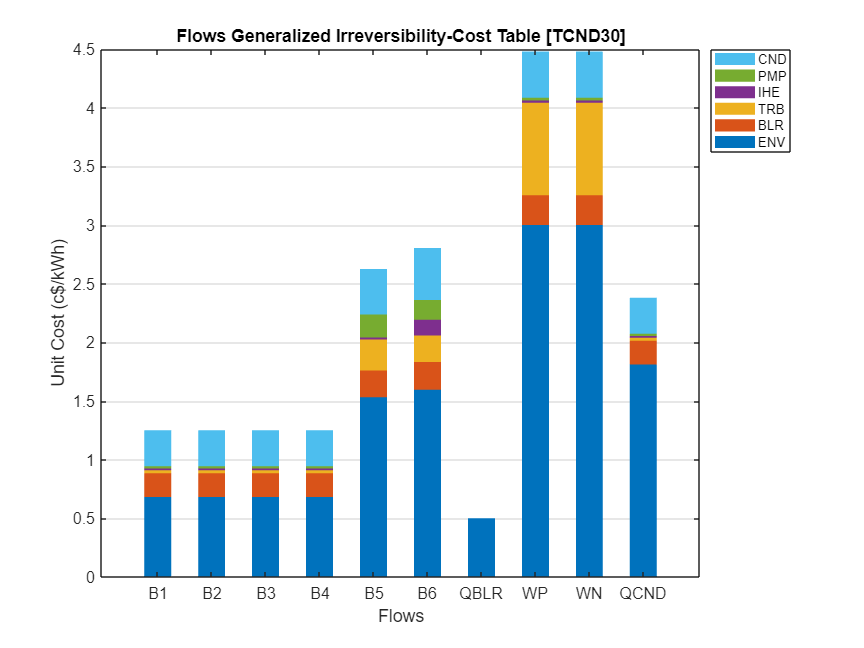

graphCost(res,cType.Tables.FLOW_GENERAL_ICT);